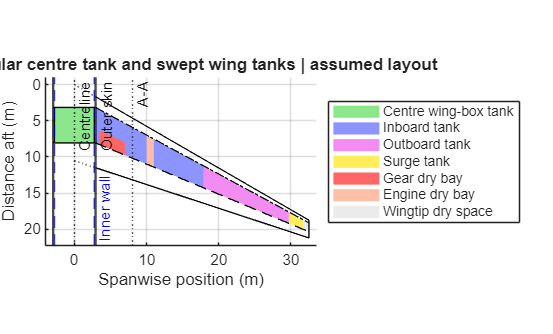

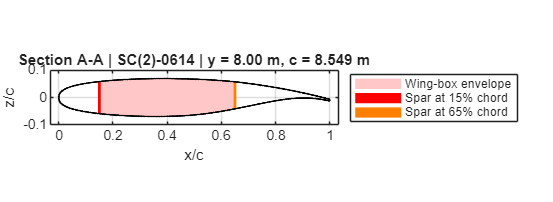


Illustrative layout only: surge and dry bays are assumed.


Root chord 10.5400 m; derived tip chord 2.4553 m; Sref 422.199 m^2


Rectangular centre tank: width 5.513 m, fore-aft length 4.905 m


Centre-box height profile assumed constant from fuselage-side airfoil.


Centre wing-box tank, full aircraft: 29.26 m^3
Inboard tank, full aircraft: 86.70 m^3
Outboard tank, full aircraft: 28.80 m^3


Surge envelope after volume factor, BOTH wings: 1.86 m^3


Total tank envelope excluding surge: 144.76 m^3


Required tank envelope: 129.73 m^3; difference: +15.03 m^3


The 0.85 factor covers unresolved structure; avoid counting resolved structure twice.


Section fill shows envelope; spar widths are illustrative, not strength sizing.


%% Fuselage sizing: 150 pax, 40 t cargo, twin aisle, LD4 + LD8 rows
clear; clc;

in2m = 0.0254;
ft2m = 0.3048;
params = readtable("Key_Param_recording.csv", 'ReadRowNames', true);
% 1. Passengers and their baggage
n_first = params{"n_first","Value"}; % 36
n_eco = params{"n_eco","Value"}; % 150-36
n_pax = n_first + n_eco;
params{'n_pax', 'Value'} = n_pax;
m_pax = params{"m_pax","Value"}; % 84, kg, EASA standard adult, includes 6 kg hand baggage
m_hand = params{"m_hand","Value"}; % 0, kg, hand baggage (inside the 84 kg), stowed in the cabin
m_chk = params{"m_chk","Value"}; % 15, kg, checked bag, EASA intercontinental
rho_bag = params{"rho_bag","Value"}; % 200, kg/m^3
eta = params{"eta","Value"}; % 0.875, loading efficiency (75-100 %)
eta_bag =0.85;% constant given
W_chk = params{"W_chk","Value"};
V_chk = W_chk/(rho_bag*eta_bag); % 13.24 m^3
params{'V_chk','Value'} = V_chk;
W_pax = params{"W_pax","Value"};
%% 2. Cargo volume (freight + checked bags)
W_cargo = params{"W_cargo","Value"}; % 40*10^3, kg
rho_cargo = params{"rho_cargo","Value"}; % 160 old; 240 new, kg/m^3
V_cargo = W_cargo/(rho_cargo*eta); % 190.48 m^3
params{'V_cargo','Value'} = V_cargo;
V_req = V_cargo + V_chk; % 203m^3
params{'V_req','Value'} = V_req;
%% 3. ULD row across: LD3 *2(Roskam)
V_row = params{"V_LD3","Value"} * 2;% 4.5* 2
params{'V_row','Value'} = V_row;
%W_row = (params{"W_LD4_in","Value"} + params{"W_LD8_in","Value"}) * in2m; % (96 + 125)*in2m, m, top widths
%W_row = params{"W_LD4_in","Value"} *2 * in2m; % (96*2)*in2m, m, top widths
W_row = params{'W_LD3_in','Value'} *2 * in2m;
params{'W_row','Value'} = W_row;
depth = params{"ULD_depth_in","Value"} * in2m; % 1.534 m, along the fuselage

N_rows = ceil(V_req/V_row) % 23 rows in total
params{'N_rows','Value'} = N_rows;
%% 4. Cabin width (economy 3-3-3, two aisles)
b_eco = params{"b_eco_in","Value"} * in2m; % 57*in2m, Roskam, 3-seat block
aisle = params{"aisle_eco_in","Value"}* in2m; % 20*in2m, Torenbeek B min
Two_side = 0 * in2m; % 2*in2m
W_cabin = 3*b_eco + 2*aisle + 2*Two_side % 5.4610 m
params{"L_2_bed","Value"} = 1.85*2;
params{'W_cabin','Value'} = W_cabin;
b_bus = params{"b_bus","Value"} * in2m; 
b_bus_1= params{"b_bus_1","Value"} * in2m; 
b_norm = params{"b_norm","Value"} * in2m; 
W_eco = b_eco *3+ aisle *2 + Two_side*2;
W_norm = b_norm*3 + aisle *2 + Two_side*2;
params{'W_norm','Value'} = W_norm;
params{'W_eco','Value'} = W_eco;
W_bu= b_bus + b_bus_1*2 + aisle *2 + Two_side*2;
params{'W_bu','Value'} = W_bu;

cabin_class_name={'Bussiness';'Premimium - eco';'Eco'};
Cabin_Width_3 = {W_bu;W_norm;W_eco};
% List width for 3 class carbin
Cabin_result_table = table(cabin_class_name, Cabin_Width_3, ...
    'VariableNames', {'Class name', 'Width'})

%% 5. Vertical constraints
H_aisle = params{"headroom_base_m","Value"} + params{"headroom_margin_m","Value"}; % 1.95 + 0.01, m, Torenbeek
params{'H_Headroom','Value'} = H_aisle;
H_cargo = params{"ULD_height_in","Value"} * in2m; % 64*in2m, m, all ULDs are 64 in tall
params{'H_cargo','Value'} = H_cargo;
wall_thickness_in = params{"wall_thickness_in","Value"};
wall_thickness = wall_thickness_in * in2m; % 3*in2m, 2-4 in
H_arm = params{"armrest_height_in","Value"} * in2m; % 25*in2m, Torenbeek (check the figure here remeber, warning warning lmao, forsure i will forget)

%% 6. Sweep inner radius
%% Solve inner radius from height geometry
syms R_sym X_sym


eq1 = 2*R_sym == (1.96 + 1.6256 + X_sym)/0.95;
eq2 = R_sym^2 == (R_sym - X_sym)^2 + 1.562^2;

sol = solve([eq1, eq2], [R_sym, X_sym]);

R_all = double(sol.R_sym);
X_all = double(sol.X_sym);

% Select the positive physical solution
idx = find(isreal(R_all) & R_all > 0 & ...
           isreal(X_all) & X_all > 0, 1);

if isempty(idx)
    error('No positive physical solution found.');
end
R_in = max(R_all(idx));
X_value = max(X_all(idx));

%y_floor_upper_surface = (R_in - X_value - 0.05 * D_inner -1.6256);
R_in_new = R_in:0.001:8;
y_floor_upper_surface2=R_in- X_value - 0.05 * 2*R_in -1.6256

k=find(R_in_new >= ((W_cabin/2)^2+(1.0414-abs(R_in_new- X_value - 0.05 * 2*R_in_new -1.6256)).^2).^0.5,1,"first")
R_in = R_in_new(k)
D_inner = R_in_new(k)*2
y_floor_upper_surface=R_in_new(k)- X_value - 0.05 * 2*R_in_new(k) -1.6256


y_floor_upper_surface - y_floor_upper_surface2
D_outer = D_inner + 2*wall_thickness;
%1.0414-
params{'y_floor_upper_surface','Value'} = y_floor_upper_surface;
params{'D_inner','Value'} = D_inner;
params{'D_outer','Value'} = D_outer;
params{'X_hold_below','Value'} = X_value;

fprintf('Inner radius = %.4f m\n', R_in);
fprintf('Inner diameter = %.4f m\n', D_inner);
fprintf('Outer diameter = %.4f m\n', D_outer);
fprintf('X = %.4f m\n', X_value);

%% 7. Seats
n_first_rows =ceil(n_first/4); % 5
params{'n_first_rows','Value'} = n_first_rows;
n_eco_rows = ceil(((n_eco-36)/9)+(36/6)); % 14 rows
params{'n_eco_rows','Value'} = n_eco_rows;
n_rows_cab = n_first_rows + n_eco_rows;
params{'n_rows_cab','Value'} = n_rows_cab;
Total_seat_pitch = (n_first_rows*36 + n_eco_rows*32)*in2m; % m
params{'Total_seat_pitch','Value'} = Total_seat_pitch;

%% 8. Cabin length
L_wc = 2 *params{"wc_length_m","Value"}; % 1*2, m, 3 lavatories: 2 back, 1 front
V_galley1 = n_pax*params{"galley_vol_per_pax_ft3","Value"}*ft2m^3; % m^3, 2 ft^3 per pax
V_galley = ft2m^3*(24*5+126)

params{'V_galley','Value'} = V_galley;
L_galley_front = V_galley*0.25/((b_eco)*H_aisle)
params{'L_galley_front','Value'} = L_galley_front;
L_galley_back = V_galley*0.75/((W_cabin-1)*H_aisle)
params{'L_galley_back','Value'} = L_galley_back;
L_galley = L_galley_back+L_galley_front
params{'L_galley','Value'} = L_galley;
L_cross = ceil(n_rows_cab/20)*1; % m
params{'L_cross','Value'} = L_cross;
exit_door_large=params{"exit_door_large_in","Value"}*in2m;
exit_door_small=params{"exit_door_small_in","Value"}*in2m;
if L_cross<exit_door_large
    disp("we cooked!!")
end
if exit_door_small>(32-18)*in2m
    add_spare = exit_door_small-(32-18)*in2m;
    disp("alr add some foot space for on wing exit: (m) "+add_spare)
end
    L_cabin = Total_seat_pitch + L_wc/2 + L_galley_front +L_galley_back+ L_cross+ add_spare +exit_door_large;

%% 9. Nose and tail
Ln_d = params{"Ln_d","Value"}; % 1.5, ASSUMPTION: Raymer M_DD chart - min alr
Lt_d = params{"Lt_d","Value"}; % 1,75, round tail
L_nose = Ln_d*D_outer;
params{'L_nose','Value'} = L_nose;
L_tail = Lt_d*D_outer; % round
params{'L_tail','Value'} = L_tail;

%% 10. Constant-section length: underfloor hold + main deck behind the cabin
f = params{"f_const_section","Value"}; % 0.65, fraction of constant-section length available for underfloor hold

% Required underfloor hold length
L_hold_req = N_rows * depth;
% Constant-section length required so that 65% can accommodate the hold
fraction = params{"fraction_hold","Value"}; % 0.64
L_under = L_hold_req / f* fraction;
params{'L_under','Value'} = L_under;
% Rest space for pilot and crew, 1 or 2 for the pilot and 2 for crew
W_bed= params{'W_bed','Value'};
bed_margin=params{'bed_margin','Value'};
L_cabin_new = L_cabin + W_bed *1*bed_margin;
Upper_cargo_length = L_under * (1-fraction);
L_main = L_cabin_new + L_under * (1-fraction);
params{'L_main','Value'} = L_main;
params{'L_cabin','Value'} = L_cabin_new;
Tot_under = L_nose + L_under + L_tail;
params{'Tot_under','Value'} = Tot_under;
Tot_upper = L_nose + L_main + L_tail;
params{'Tot_upper','Value'} = Tot_upper;

L_vertical_stabiliser = params{"L_vertical_stabiliser","Value"};
L_total = max(Tot_upper, Tot_under)+L_vertical_stabiliser;
params{'L_total','Value'} = L_total;

fprintf(['\n Total length is %.3f m, \n with cabin length %.3f m, \n Upper cargo length %.3f m, ' ...
    '\n upper total length is %.3f m \n Lower cargo length is %.3f m \n with %.3f m rest space. \n D_outer and D_inner: %.3f m and %.3f m \n with %.0f inch wall stickness \n Current Cargo density = %.0f kg/m^3'], ...
    L_total,L_cabin_new,Upper_cargo_length,(Upper_cargo_length+L_cabin_new),L_under,(L_under-(Upper_cargo_length+L_cabin_new)),D_outer,D_inner,wall_thickness_in,rho_cargo);
writetable(params, "Key_Param_recording.csv", 'WriteRowNames', true);
